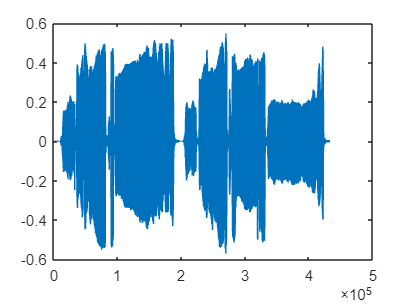


close all;
flute = "C:\Users\Rebecka\Documents\Liu\Kurser\Ljudteknik\TNM103-Ljudteknik\429064__carloscarty__dizi-flute-loop-21-120-bpm.wav";
[y, Fs] = audioread(flute);

orginal = audioplayer(y, Fs);
%orginal.play;

%f1 = figure;
%subplot(211)
% orginal ska det egentligen vara 
%subplot(212)


% ---- Speed = 1 orginal temp, speed = 0.5 halva osv

speed = 2;
windowSize = round(1 * 0.05 * Fs);
stepSize = round(windowSize * speed);

newFrame = zeros(round(length(orginal) * (windowSize / stepSize) + windowSize), 1);
k = 1;
for i = (0:stepSize:length(y) - 1)
    for j = (0:1:windowSize -1)

        newFrame(k) = i + j + 1;
        k = k + 1;

    end
end

ix = newFrame > 0;
newFrame = newFrame(ix);

ix = newFrame <= length(y);
newFrame = newFrame(ix);

phaseVocodedSound = y(newFrame);

mixsound = audioplayer(phaseVocodedSound, Fs);
%mixsound.play;

plot(y)

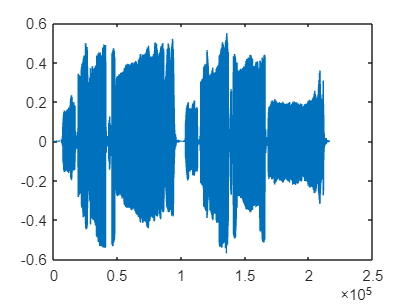

plot(phaseVocodedSound)



%-------- Pitch

pitch = 0.5;
Fs2 = Fs * pitch;

mixsoundpitch = audioplayer(phaseVocodedSound, Fs2);
mixsoundpitch.play